% Load variables
bedMatrix_1 = load("C:\Users\louis\OneDrive\Documents\Robotic 3D Printing\bedMatrix.mat");
bedMatrix = bedMatrix_1.bedMatrix;
clear bedMatrix_1;

% Display results
bedMatrix

bedMatrix =     3.1840    3.1820    3.1810    3.1790    3.1770    3.1750    3.1730    3.1710    3.1690    3.1670    3.1650    3.1630    3.1620    3.1600    3.1580    3.1560    3.1540    3.1520    3.1500    3.1480    3.1460    3.1440    3.1430    3.1410    3.1390    3.1370    3.1350    3.1330    3.1310    3.1290    3.1270    3.1250    3.1240    3.1220    3.1200    3.1180    3.1160    3.1140    3.1120    3.1100    3.1080    3.1060    3.1050    3.1030    3.1010    3.0990    3.0970    3.0950    3.0930    3.0910
    3.1840    3.1820    3.1800    3.1780    3.1760    3.1740    3.1720    3.1710    3.1690    3.1670    3.1650    3.1630    3.1610    3.1590    3.1570    3.1550    3.1540    3.1520    3.1500    3.1480    3.1460    3.1440    3.1420    3.1400    3.1380    3.1370    3.1350    3.1330    3.1310    3.1290    3.1270    3.1250    3.1230    3.1210    3.1200    3.1180    3.1160    3.1140    3.1120    3.1100    3.1080    3.1060    3.1040    3.1030    3.1010    3.0990    3.0970    3.0950    3.0

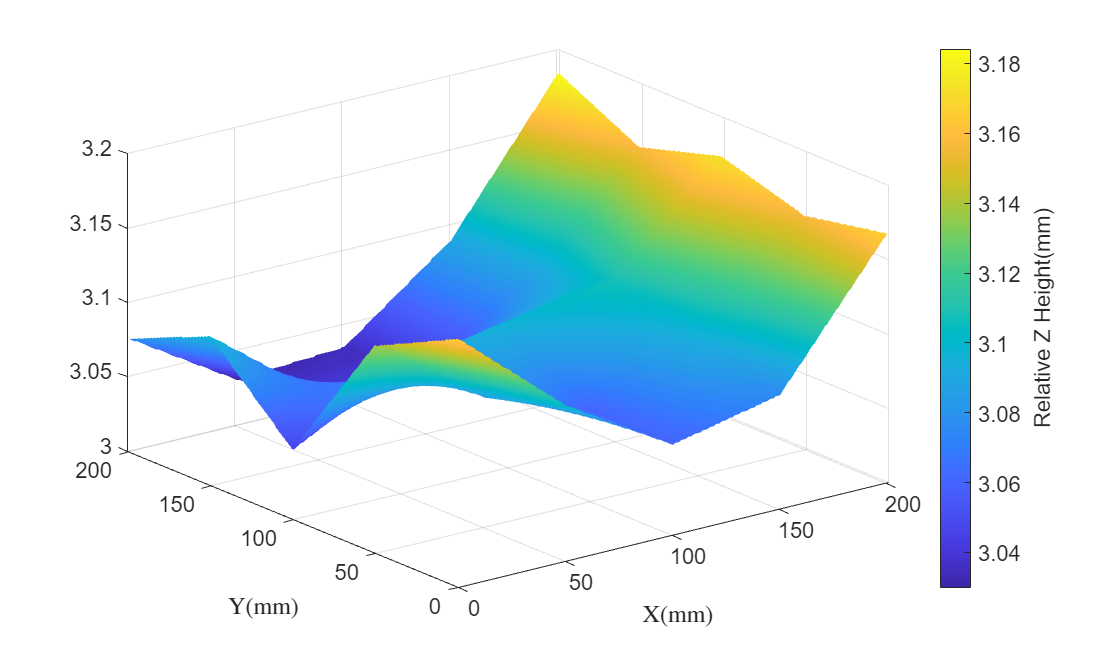


x = flip([1:201]);
y = flip([1:201]);
b = bedMatrix';


surf(x,y,b')
xlim([0 200])
ylim([0 200])
% zlim([-0.3 0.3])
shading interp
cbar = colorbar;
cbar.Label.String = 'Relative Z Height(mm)';
cbar.FontSize = 12;
xlabel('X(mm)','fontsize',12,'fontweight','bold','interpreter','latex');
ylabel('Y(mm)','fontsize',12,'fontweight','bold','interpreter','latex');
set(gca,'fontsize',12)
set(gcf,'position',[0,0,1000,600])

mina = min(bedMatrix,[],"all")

mina = 3.0300

maxa = max(bedMatrix,[],"all")

maxa = 3.1840

diff = mina - maxa 

diff = -0.1540